syms theta_1(t) theta_2(t) L_1 L_2 m_1 m_2 g

x_1 = L_1*sin(theta_1);
y_1 = -L_1*cos(theta_1);
x_2 = x_1 + L_2*sin(theta_2);
y_2 = y_1 - L_2*cos(theta_2);

vx_1 = diff(x_1);
vy_1 = diff(y_1);
vx_2 = diff(x_2);
vy_2 = diff(y_2);

ax_1 = diff(vx_1);
ay_1 = diff(vy_1);
ax_2 = diff(vx_2);
ay_2 = diff(vy_2);

syms T_1 T_2

eqx_1 = m_1*ax_1(t) == -T_1*sin(theta_1(t)) + T_2*sin(theta_2(t))

$$eqx\_1 = -m_{1}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}-L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\right)=T_{2}\,\sin\left(\theta_{2}\left(t\right)\right)-T_{1}\,\sin\left(\theta_{1}\left(t\right)\right)$$

eqy_1 = m_1*ay_1(t) == T_1*cos(theta_1(t)) - T_2*cos(theta_2(t)) - m_1*g

$$eqy\_1 = m_{1}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)=T_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-g\,m_{1}-T_{2}\,\cos\left(\theta_{2}\left(t\right)\right)$$

eqx_2 = m_2*ax_2(t) == -T_2*sin(theta_2(t))

$$eqx\_2 = -m_{2}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+L_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}-L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)-L_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\right)=-T_{2}\,\sin\left(\theta_{2}\left(t\right)\right)$$

eqy_2 = m_2*ay_2(t) == T_2*cos(theta_2(t)) - m_2*g

$$eqy\_2 = m_{2}\,\left(L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+L_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+L_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\right)=T_{2}\,\cos\left(\theta_{2}\left(t\right)\right)-g\,m_{2}$$

Tension = solve([eqx_1 eqy_1],[T_1 T_2]);

eqRed_1 = subs(eqx_2,[T_1 T_2],[Tension.T_1 Tension.T_2]);
eqRed_2 = subs(eqy_2,[T_1 T_2],[Tension.T_1 Tension.T_2]);

L_1 = 1;
L_2 = 1.5;
m_1 = 2;
m_2 = 1;
g = 9.8;
eqn_1 = subs(eqRed_1)

$$eqn\_1 = \begin{array}{l} \cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}-\frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}-\sin\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{2}=-\frac{2\,\sin\left(\theta_{2}\left(t\right)\right)\,\left({\cos\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{1}+{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{1}+\frac{49\,\sin\left(\theta_{1}\left(t\right)\right)}{5}\right)}{\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)-\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right) \end{array}$$

eqn_2 = subs(eqRed_2)

$$eqn\_2 = \begin{array}{l} \cos\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+\frac{3\,\cos\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}+\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}+\frac{3\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)}{2}=\frac{2\,\cos\left(\theta_{2}\left(t\right)\right)\,\left({\cos\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{1}+{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,\sigma_{1}+\frac{49\,\sin\left(\theta_{1}\left(t\right)\right)}{5}\right)}{\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)-\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)}-\frac{49}{5}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right) \end{array}$$

[V,S] = odeToVectorField(eqn_1,eqn_2);

S

$$S = \left(\begin{array}{c} \theta_{2}\\ {\mathrm{Dtheta}}_{2}\\ \theta_{1}\\ {\mathrm{Dtheta}}_{1} \end{array}\right)$$

M = matlabFunction(V,'vars',{'t','Y'});

initCond = [pi/4 0 pi/6 0];
sols = ode45(M,[0 10],initCond);

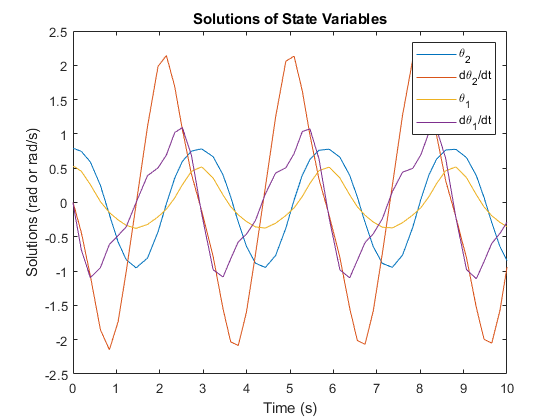

plot(sols.x,sols.y)
legend('\theta_2','d\theta_2/dt','\theta_1','d\theta_1/dt')
title('Solutions of State Variables')
xlabel('Time (s)')
ylabel('Solutions (rad or rad/s)')

x_1 = @(t) L_1*sin(deval(sols,t,3));
y_1 = @(t) -L_1*cos(deval(sols,t,3));
x_2 = @(t) L_1*sin(deval(sols,t,3))+L_2*sin(deval(sols,t,1));
y_2 = @(t) -L_1*cos(deval(sols,t,3))-L_2*cos(deval(sols,t,1));

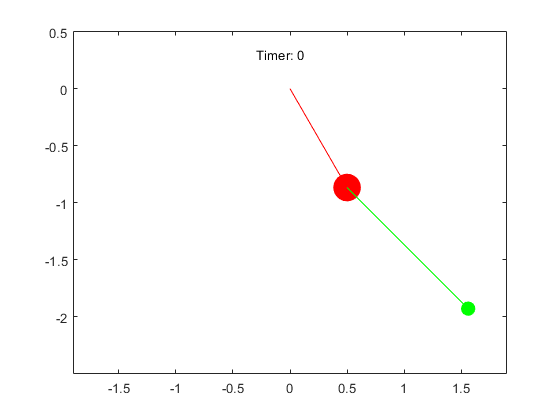

fanimator(@(t) plot(x_1(t),y_1(t),'ro','MarkerSize',m_1*10,'MarkerFaceColor','r'));
axis equal;
hold on;
fanimator(@(t) plot([0 x_1(t)],[0 y_1(t)],'r-'));
fanimator(@(t) plot(x_2(t),y_2(t),'go','MarkerSize',m_2*10,'MarkerFaceColor','g'));
fanimator(@(t) plot([x_1(t) x_2(t)],[y_1(t) y_2(t)],'g-'));
fanimator(@(t) text(-0.3,0.3,"Timer: "+num2str(t,2)));
hold off;

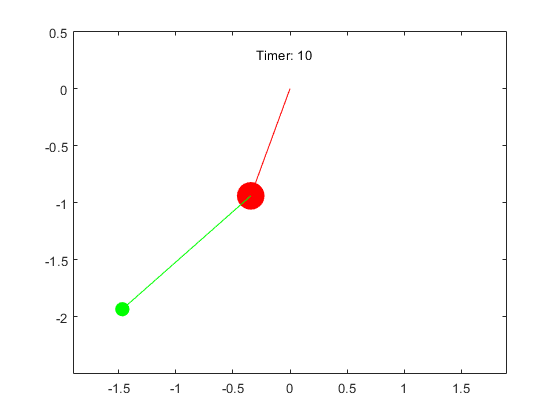

playAnimation